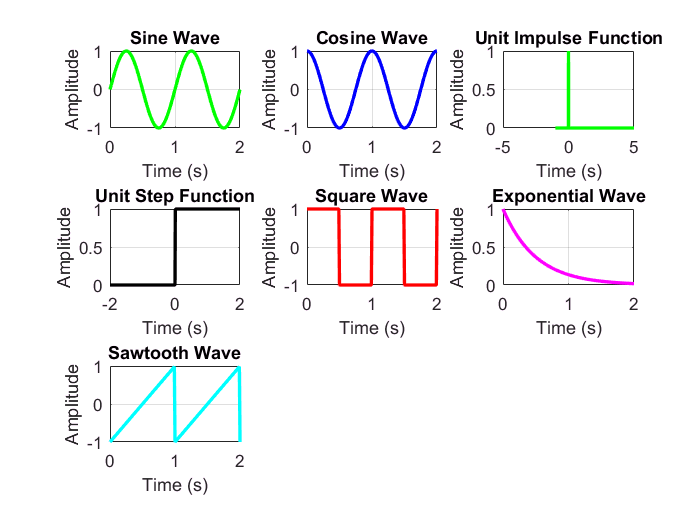

clear all;
clc;

% Define Time Vector with a shorter range to visualize waves better
t = 0:0.01:2;  % Time from 0 to 2 seconds

% Input for amplitude and frequency
a = input('Enter the amplitude: ');  % Amplitude
f = input('Enter the frequency: ');  % Frequency (try smaller values like 1 or 2)

% First subplot: Sine wave
subplot(3, 3, 1);  
b = a * sin(2 * pi * f * t);  % Sine wave
plot(t, b, 'LineWidth', 2, 'Color', 'g');
xlabel('Time (s)');
ylabel('Amplitude');
title('Sine Wave');
grid on;

% Second subplot: Cosine wave
subplot(3, 3, 2);
b = a * cos(2 * pi * f * t);  % Cosine wave
plot(t, b, 'LineWidth', 2, 'Color', 'b');
xlabel('Time (s)');
ylabel('Amplitude');
title('Cosine Wave');
grid on;

% Third subplot: Unit Impulse function
t = -2:0.01:2;  
unit_impulse = zeros(size(t));
unit_impulse(t == 0) = 1;
subplot(3, 3, 3);
plot(t, unit_impulse, 'LineWidth', 2, 'Color', 'g');
xlabel('Time (s)');
ylabel('Amplitude');
title('Unit Impulse Function');
grid on;

% Fourth subplot: Unit step function
t=-2:0.01:2;
unit_step = t > 0;
subplot(3, 3, 4);
plot(t, unit_step, 'LineWidth', 2, 'Color', 'k');
xlabel('Time (s)');
ylabel('Amplitude');
title('Unit Step Function');
grid on;

% Fifth subplot: Square wave
t = 0:0.01:2;
subplot(3, 3, 5);
b = a * square(2 * pi * f * t);  % Square wave
plot(t, b, 'LineWidth', 2, 'Color', 'r');
xlabel('Time (s)');
ylabel('Amplitude');
title('Square Wave');
grid on;

% Sixth subplot: Exponential wave
t = 0:0.01:2;
amplitude = 1;  % Exponential wave amplitude
decay_rate = 2;  % Exponential wave decay rate
exp_wave = amplitude * exp(-decay_rate * t);  % Exponential wave
subplot(3, 3, 6);
plot(t, exp_wave, 'LineWidth', 2, 'Color', 'm');
xlabel('Time (s)');
ylabel('Amplitude');
title('Exponential Wave');
grid on;

% Seventh subplot: Sawtooth wave
t = 0:0.01:2;
sawtooth_wave = a * sawtooth(2 * pi * f * t);  % Sawtooth wave
subplot(3, 3, 7);
plot(t, sawtooth_wave, 'LineWidth', 2, 'Color', 'c');
xlabel('Time (s)');
ylabel('Amplitude');
title('Sawtooth Wave');
grid on;